# System parameter calculutions

The goal of this script is to compute the dimensions of the various diemnsions of the parts of the 2 stage zero stiffness variable position and mass gravity compensation. It does so using the given constraints, prefrences and part selection 

clear all; close all
addpath("Spring calcuations") %adding path for spring calculations
Trekveren = readtable('Trekveren.xlsx')

Trekveren = 435×9 table
    Artikelcode     d      Dm      Lo      fn      Fn      R        Materiaal         prijs   
    ___________    ___    ____    ____    ____    ____    ____    ______________    __________

     {'T1010'}     1.1     6.4    27.2    13.3    55.5    3.55    {'Verenstaal'}    {'€ 2,66'}
     {'T1020'}     1.1     6.4    37.1    20.8    55.5    2.28    {'Verenstaal'}    {'€ 2,66'}
     {'T1030'}     1.1     6.4    53.6    33.2    55.5    1.42    {'Verenstaal'}    {'€ 2,66'}
     {'T1040'}     1.1    10.9    27.8    26.4    35.8    1.15    {'Verenstaal'}    {'€ 2,66'}
     {'T1050'}     1.1    10.9    34.4       0    35.8    0.72    {'Verenstaal'}    {'€ 2,66'}
    

#### Material constants

g = 9.81; %[m/s^2]   gravity constant  
%alluminium
E_allu = 69E9; %   
sigma_y_allu = 124E6; %steel https://www.steelinox.nl/nl/informatie/roestvast-staal-info
%https://www.gamma.nl/assortiment/plat-profiel-rvs-15x0-5x1000mm/p/B175454
E_steel = 190E9; %[Pa] elastic modulus of steel 
sigma_y_steel = 250E6; %[Pa] yield stress steel
%pvc -> https://www.naeff.nl/nl/technische-datasheet/polyvinylchloride-pvc-u?n=2690_3
%https://www.praxis.nl/gereedschap-installatiemateriaal/ijzerwaren/profielen-platen/profielen/alberts-platte-stang-kunststof-wit-25x2mm-1m/5535075
E_pvc = 3000E6; %[Pa]
sigm_y_pvc = 58E6; %[Pa] %flow tension is used, as this is an underirable effect

#### System constants

m2 = .8;                 %[kg] unloaded mass .8
m1 = 2;         %[kg] loaded mass 2
m_s2 = 1;               %[kg] second stage mass
sys_angle = 28/180*pi;  %[rad] angle at which the mirror is located 
t = 6e-3;               %[m] thickness of plate material that will be used for construction

#### Constraints

h_max = .4;             %[m] maximal height mass compensator     
w_max  = .1;            %[m] maximal width mass compensator   
sf = 1.1; %safety margin 10%
%{
d_mirror = .16;
Longstroke = d_mirror*sin(sys_angle)*3 %[m] stroke of the first stage
S1 = Longstroke*sf 
%}
S1 = 160E-3; %long stroke mechanism
S2 = 5e-3; %short stroke mechanism

## First stage

The first stage consists out of a positive spring and a pulley mechanism

### parameters

R1 = 15E-3;             %[m] inner radius -> constraint by material design of the pulley system
F1 = m1*g + m_s2*g;     %[N] initial load on the system
F2 = m2*g + m_s2*g;     %[N] second loading condition
h_mech = 5*t;           %[m] 5 plate material of space needed for construction
SR = 1/3;               %[] spring elongation ratio

### Desired properties

    stage1 = springsystem(F1,F2,S1,h_mech,h_max,SR, 10E-3); %defining the spring system
stage1 = stage1.comp_sys(2) %computing the system properties

stage1 =   springsystem with properties:

              F1: 29.4300
              F2: 17.6580
              L0: 0.1024
              L1: 0.0448
              L2: 0.0269
            Lmax: 0.3072
               S: 0.1600
    springstroke: []
      max_stroke: 0
              R1: 0.0100
              R2: 0.0448
          h_mech: 0.0300
        h_adjust: 0.0179
           h_max: 0.4000
               k: 656.4700
              SR: 0.3333
          Fn_tot: []


stage1.desired_properties()

    "k = 656.47"

    "l0 = 102.4123"

    "fn = 204.8307"

    "Fn = 134.4652"



### Spring selection

Bellow various springs parameters are inserted and the function keeps the best spring parameters.

best_spring = table()


best_spring =

  0×0 empty table




for i = 1 : height(Trekveren)
    spring = Trekveren(i,:);
    
    
    for j = 1 : 2 %Trying out different spring amounts      
        [stage1, b] = stage1.better_spring(spring.Lo, spring.fn, spring.Fn, j);
        if b
            T = spring;
            T.('n') = j;
            T.('stroke') = stage1.max_stroke;
            best_spring = [best_spring; T];
        end
        
    end
end

Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found



best_spring

best_spring = 13×11 table
    Artikelcode     d       Dm      Lo       fn       Fn       R        Materiaal         prijs       n     stroke  
    ___________    ____    ____    _____    _____    _____    ____    ______________    __________    _    _________

     {'T1010'}      1.1     6.4     27.2     13.3     55.5    3.55    {'Verenstaal'}    {'€ 2,66'}    1    0.0062475
     {'T1010'}      1.1     6.4     27.2     13.3     55.5    3.55    {'Verenstaal'}    {'€ 2,66'}    2    0.0097738
     {'T1020'}      1.1     6.4     37.1     20.8     55.5    2.28    {'Verenstaal'}    {'€ 2,66'}    2     0.015286
     {'T1030'}

### Pulley design

figure()
clf
hold on
for i = 1:2
    if i == 1 %selecting the loading condition 
        F0 = stage1.F1
    else
        F0 = stage1.F2
    end
    r1 = stage1.R1;
    r2 = stage1.R2;
        k = stage1.k;
    S = F0*r2/k;
    T = F0*r2/(k*r1);
    n_steps = 800;
    stepsize = (r2- r1)/n_steps;
    r = [r1:stepsize:r2];
    theta = -sqrt(S^2- r.^4)./(2*r.^2) + 0.5 *asin(r.^2/S) ;
    const = theta(1);
    theta = theta - const; %adding constant such that theta(1) = 0
    x = real(cos(theta).*r*1e3);
    y = real(sin(theta).*r*1e3);
    output = table(transpose(x),transpose(y));
    writetable(output,'curve.xlsx');
    plot(x,y)
end

F0 = 29.4300

F0 = 17.6580

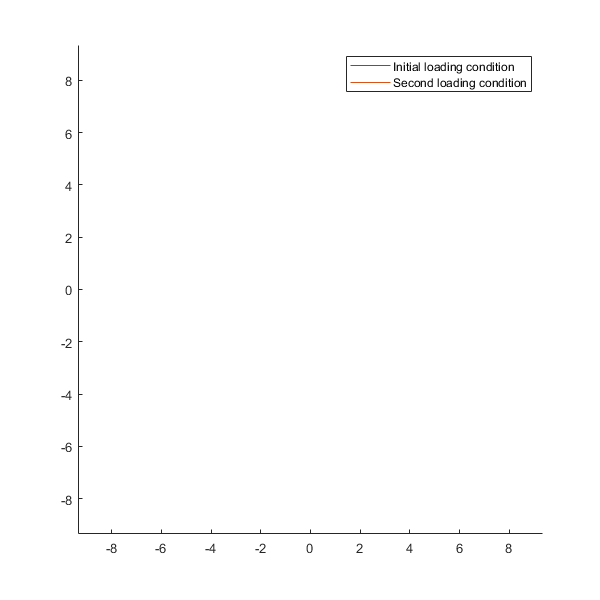

legend('Initial loading condition','Second loading condition')
set(gcf, 'Position',  [100, 100, 600, 600])

xlim([-r2,r2]*1e3)
ylim([-r2,r2]*1e3)

## Second stage 

The second stage consist out of two parts, the negative spring system and the positive spring system

### parameters

F1 = m1*g;      %[N] initial load on the system
F2 = m2*g;      %[N] second loading condition
R = 0.9;        %[]desired stiffness reduction
n = 4;          %[]number of leaf springs
SR = 1/2;       %[]spring ratio is lower with smaller sizes
h_mech = 5*t;   %[]height positive spring construction
h_max = round(stage1.h_max - 2*stage1.R2 - stage1.S, 2);%second stage maximal height
h2n = S2 * 8;           %[m] max heigh negative spring
h2p = h_max - h2n;      %[m] max height positive spring
h_max, h2n, h2p %printing out the resulting dimensions

h_max = 0.1900

h2n = 0.0400

h2p = 0.1500

### Desired positive spring

stage2p = springsystem(F1,F2,S2,h_mech,h2p,SR,0); %creating the secondstage positive spring system
stage2p = stage2p.comp_sys(2) %computing the system parameters 

stage2p =   springsystem with properties:

              F1: 19.6200
              F2: 7.8480
              L0: 0.0473
              L1: 0.0423
              L2: 0.0169
            Lmax: 0.0946
               S: 0.0050
    springstroke: []
      max_stroke: 0
              R1: 0
              R2: 0
          h_mech: 0.0300
        h_adjust: 0.0254
           h_max: 0.1500
               k: 463.7500
              SR: 0.5000
          Fn_tot: []


stage2p.desired_properties() %showing desired spring properties

    "k = 463.75"

    "l0 = 47.3078"

    "fn = 47.3073"

    "Fn = 21.9387"




best_spring = table()


best_spring =

  0×0 empty table




for i = 1 : height(Trekveren)
    spring = Trekveren(i,:);
    
    
    for j = 1 : 2 %Trying out different spring amounts      
        [stage2p, b] = stage2p.better_spring(spring.Lo, spring.fn, spring.Fn, j);
        if b
            T = spring;
            T.('n') = j;
            T.('stroke') = stage2p.max_stroke;
            best_spring = [best_spring; T];
        end
        
    end
end

Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found
Better spring found


best_spring

best_spring = 13×11 table
    Artikelcode     d      Dm      Lo      fn      Fn      R        Materiaal         prijs       n     stroke  
    ___________    ___    ____    ____    ____    ____    ____    ______________    __________    _    _________

     {'T1010'}     1.1     6.4    27.2    13.3    55.5    3.55    {'Verenstaal'}    {'€ 2,66'}    1    0.0085983
     {'T1010'}     1.1     6.4    27.2    13.3    55.5    3.55    {'Verenstaal'}    {'€ 2,66'}    2     0.010949
     {'T1020'}     1.1     6.4    37.1    20.8    55.5    2.28    {'Verenstaal'}    {'€ 2,66'}    1     0.013446
     {'T1020'}     1.1     6.4    